**Angabe:**

clear all

syms t tau

% dx/dt = A*x + B*u
%     y = c^T*x

A = [1 -2; 0 3] % ← anpassen!

A =      1    -2
     0     3


B = [-2 0; 2 1]   % ← anpassen!

B =     -2     0
     2     1


cT = [-5 7]        % ← anpassen!

cT =     -5     7



Ta = 1          % ← anpassen!

Ta = 1


% x_{k+1} = Phi*x_k + Gamma*u_k
%     y_k = c^T*x_k

**Explizites Eulerverfahren | Skript 2022 S.141 | DANKE @Bernd!**

Phi = eye(2)+Ta*A

Phi =      2    -2
     0     4


Gamma = Ta*B

Gamma =     -2     0
     2     1


**Exakte Lösung | Skript 2022 S.142 f.**

expA = expm(A*t);
Phi = subs(expA, t, Ta)            % ← Lösung!

$$Phi = \left(\begin{array}{cc} \mathrm{e} & \mathrm{e}-{\mathrm{e}}^{3}\\ 0 & {\mathrm{e}}^{3} \end{array}\right)$$

Gamma = int(expm(A*tau)*B, 0, Ta)  % ← Lösung!

$$Gamma = \left(\begin{array}{cc} \frac{2}{3}-\frac{2\,{\mathrm{e}}^{3}}{3} & -\frac{{\left(\mathrm{e}-1\right)}^{2}\,\left(\mathrm{e}+2\right)}{3}\\ \frac{2\,{\mathrm{e}}^{3}}{3}-\frac{2}{3} & \frac{{\mathrm{e}}^{3}}{3}-\frac{1}{3} \end{array}\right)$$

**Erreichbarkeitsmatrix**

% x_{k+1} = Phi*x_k + Gamma*u_k
Phi = [-161/2, -70, 7/2, -9/2; 82, 71, -4, 5; -29/2, -14, -13/2, -1/2; 30, 28, -2, -4] % ← anpassen!

Phi =   -80.5000  -70.0000    3.5000   -4.5000
   82.0000   71.0000   -4.0000    5.0000
  -14.5000  -14.0000   -6.5000   -0.5000
   30.0000   28.0000   -2.0000   -4.0000


Gamma = [5/2; -5/2; 1/2; -1]                                                                   % ← anpassen!

Gamma =     2.5000
   -2.5000
    0.5000
   -1.0000



% Satz 7.3 - Muss angepasst werden, wenn Phi nicht 4x4 ist!
R = [Gamma, Phi*Gamma, Phi^2*Gamma, Phi^3*Gamma]

R =     2.5000  -20.0000  125.0000 -755.0000
   -2.5000   20.5000 -128.5000  776.5000
    0.5000   -4.0000   25.0000 -151.0000
   -1.0000    8.0000  -50.0000  302.0000


rank(R) % ← Lösung!

ans = 2

**Erreichbarer Unterraum**

R_err = [R(:,1:1:rank(R))]

R_err =     2.5000  -20.0000
   -2.5000   20.5000
    0.5000   -4.0000
   -1.0000    8.0000


**Vektor des nicht erreichbaren Unterraums**

syms a b c

d = 1; % ← muss ggf. angepasst werden!
w = [a, b, c, d];

eq1 = dot(w, R_err(:,1)) == 0; % Zahl Gleichungen = Rang(R)
eq2 = dot(w, R_err(:,2)) == 0;
sol = solve([eq1, eq2], [a, b, c]);
w = [sol.a; sol.b; sol.c; d] % ← Lösung!

$$w = \left(\begin{array}{c} \frac{2}{5}\\ 0\\ 0\\ 1 \end{array}\right)$$

**Zustandsrückführung**

% p(z) = p_0 + p_1*z + p_2*z^2 + p_3*z^3
p_0 = 1/50 % ← anpassen!

p_0 = 0.0200

p_1 = -3/10 % ← anpassen!

p_1 = -0.3000

p_2 = 1   % ← anpassen!

p_2 = 1


Phi = [0 1 ; -6 -7] % ← anpassen!

Phi =      0     1
    -6    -7


Gamma = [0; 1]              % ← anpassen!

Gamma =      0
     1



% Satz 7.3 - Muss angepasst werden, wenn Phi nicht 3x3 ist!
R = [Gamma, Phi*Gamma];

% Satz 8.2 - Muss angepasst werden, wenn Phi nicht 3x3 ist!
v_1 = [a; b];
e_n = [0; 1];
eq4 = transpose(e_n) == transpose(v_1)*R; %evtl. statt e_n Gamma - bei mir leider ident...
sol = solve(eq4, [a b]);
v_1 = [sol.a; sol.b];
k_T = -p_0*transpose(v_1)-p_1*transpose(v_1)*Phi-p_2*transpose(v_1)*Phi^2

$$k\_T = \left(\begin{array}{cc} \frac{299}{50} & \frac{73}{10} \end{array}\right)$$


% Kontrolle:
double(eig(Phi+Gamma*k_T))

ans =     0.1000
    0.2000


roots([p_2 p_1 p_0]) % Reihenfolge ist egal, aber die Werte müssen gleich sein

ans =     0.2000
    0.1000


**Dead-Beat Beobachter, Teil 1**

syms q r s z

Phi = [19/16 -1 57/16; 9/16 0 11/16; -13/16 1 -39/16]

Phi =     1.1875   -1.0000    3.5625
    0.5625         0    0.6875
   -0.8125    1.0000   -2.4375


Gamma = [19/2; 3/2; -9/2]

Gamma =     9.5000
    1.5000
   -4.5000


c = [1; 0; 3]

c =      1
     0
     3



% Skript S.217
% p_{g,soll} = z^3

k = [q; r; s];
p_g = det(z*eye(3)-(Phi+k*c.'));
k_p = coeffs(p_g, z);
eq5 = k_p(1) == 0;
eq6 = k_p(2) == 0;
eq7 = k_p(3) == 0;
sol = solve([eq5 eq6 eq7], [q,r,s]);
k = [sol.q; sol.r; sol.s]

$$k = \left(\begin{array}{c} -\frac{19}{16}\\ -\frac{1}{16}\\ \frac{13}{16} \end{array}\right)$$


% Kontrolle:
double(eig(Phi+k*c.')) % soll der Nullvektor sein

ans =      0
     0
     0


**Dead-Beat Beobachter, Teil 2**

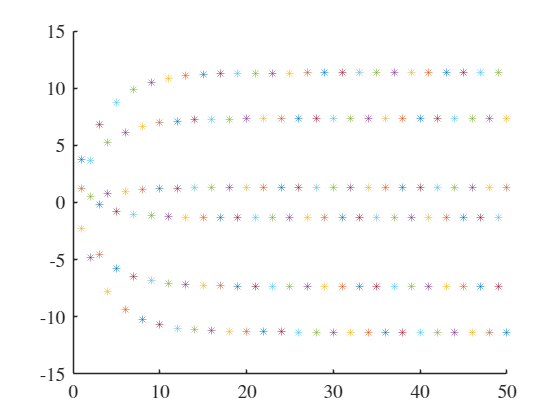

% Skript S.222
% e_{k+1} = Phi*(x_{0,hat}-x_0)
% e_0 = (x_{0,hat}-x_0)

e = [1; 1; 1];

hold on
for r = 1:50
    e = Phi*e;
    scatter(r, e, '*')
end

% sollte eindeutig sein - mit meinen Werten kommt lim = inf heraus

Gernot Polivka | 12009686 | 